# Propagation through scattering examples

This script gives a few short examples of how to use the multi-layer/multi-slab Rytov/Born propagation models

Grids:

clear variables
ps          = .105;                 % pixel size (x,y,z) in object space (microns)
lambda      = 0.5;                  % central wavelength (microns)
NA          = 1.0;                  % numerical aperture of imaging and detection lens
n_imm       = 1.367;                % refractive index of immersion media
k0=(2*pi)/lambda;
k=k0*n_imm;
c=(3e8)*1e6*1e-15;                  % speed of light microns per fs
N           = 2^9;                  % lateral pixel dimension 
x           = ps*[-N/2:N/2-1];      % 1D axis in x
y=x;
dfx         = 1/(N*ps);             % Fourier spacing of padded axis
[X Y]=meshgrid(x,y);
fx          = dfx*[-N/2:N/2-1];     % 1D axis in fx
[fxx,fyy]   = meshgrid(fx,fx);      % 2D grid in fx/fy

fx          = ifftshift(fx);        % FFT shifting Fourier axes
fxx         = ifftshift(fxx);       % FFT shifting Fourier axes
fyy         = ifftshift(fyy);       % FFT shifting Fourier axes

Building 3D scattering material with MW correlation function

%% Building 3D RI material and scattering potential
l=.5;                 % Correlation length (um)
sigma=.01;            % standard deviation of RI
% Both match what is seen in actual tissue (see Min Xu's paper: "Scattering-phase theorem: anomalous diffraction by forward-peaked scattering media")

nu=1;
RImodel='MW';

musMWred=@(l,nu,sig,k) sqrt(pi)*(1./l).*(sig^2).*(gamma(nu+.5)./abs(gamma(nu))).*(1./(nu-.5)).*(1-((1+4.*(k.*l).^2).^(-nu-.5)).*(1+4.*((k.*l).^2).*(nu+.5)));
mu_sMWa=@(l,nu,sig,k) 2*sqrt(pi)*(k^2).*l.*(sig^2).*(gamma(nu+.5)./abs(gamma(nu))).*(1-(1+4.*(k.*l).^2).^(-nu-.5));
mu_sMW=mu_sMWa(l,nu,sigma,k);%2*sqrt(pi)*(k^2)*l*(sigma^2)*(gamma(nu+.5)/abs(gamma(nu)))*(1-(1+4*(k*l)^2)^(-nu-.5));

if nu==.5
    mu_sMWr=(musMWred(l,.5-.00000001,sigma,k)+musMWred(l,.5+.00000001,sigma,k))/2;
else
%mu_sMWr=sqrt(pi)*(1/l)*(sigma^2)*(gamma(nu+.5)/abs(gamma(nu)))*(1/(nu-.5))*(1-((1+4*(k*l)^2)^(-nu-.5))*(1+4*((k*l)^2)*(nu+.5)));
mu_sMWr=musMWred(l,nu,sigma,k);
end

g_MW=1-mu_sMWr/mu_sMW;
g_MWa=@(l,nu,sig,k) 1-musMWred(l,nu,sig,k)./mu_sMWa(l,nu,sig,k);
disp(append('Scattering Length is:',num2str(1/mu_sMW),' ','microns'))

Scattering Length is:21.5779 microns


disp(append('Scattering Anisotropy is:',num2str(g_MWa(l,nu,sigma,k0))))

Scattering Anisotropy is:0.97767



%% z Direction
L=4*(1/mu_sMW); %Thickness of media in microns
Nz=round(L/ps)+1;
if mod(Nz,2)==0
    Nz=Nz+1;
end

z=ps*[-Nz/2:Nz/2-1];
zz=ps*[1:Nz];
fz          = dfx*[-Nz/2:Nz/2-1];  
disp(append('Thickness of RI is',' ',num2str(L*mu_sMW),' ','scattering lengths'))

Thickness of RI is 4 scattering lengths


[RI sdev avg]=RIGenerator3D(RImodel,l,sigma,nu,x,y,z,'single');
%disp(append('std is off by ','',num2str(-(sigma-sdev)/sigma*100),'%'))
RI=RI-avg;
%if abs(-(sigma-sdev)/sigma*100)>.2
RI=RI*(sigma/sdev); % Rescaling std

Setting input field:

NA=n_imm*sin(x(end)*pi*n_imm*.61/2/L)              % Set NA so that the size of the beam at the entrance of the material is small enough such that it will not be cut off

NA = 0.5403


prop_crop = (fxx.^2 + fyy.^2 > (n_imm/lambda)^2==0);
prop_phs= 1i*2*pi*sqrt((n_imm/lambda)^2-(fxx.^2+fyy.^2));
prop_phs=prop_phs.*prop_crop;
prop=@(z) exp(prop_phs*z);
PropField=@(U,z) ifft2(prop(z).*(fft2(U)));
W0=.61*lambda/asin(NA/n_imm);                      % Beam waist at center wavelength
                                                   % k=w/c
        s= @(w) sqrt((w/c)/k0)*W0;                 % Beam waist as function of wavelength
        z0=@(w) pi*(s(w/c))^2/lambda;              % Rayleigh range
        %At=exp(-(t/(t0a)).^2);                    % Gaussian temporal pulse profile
        S=@(w,z) sqrt(s(w).^2*(1+(z/z0(w)).^2));   % Waist size as function of z. z=0 is location of waist
        R=@(w,z) z*(1+(z0(w)/z)^2);                % Radius of wavefront
        q=@(w,z) 1/(R(w,z))-1i*(2/(k0*S(w,z)^2));  % complex beam parameter
        phi=@(w,z) atan(z/z0(w));                  % Axial phase

        E0=100;
        %E=@(r,w,z) E0*t0*sqrt(2)*exp(-t0^2*(w-w0).^2).*(W0./S(w,z)).*exp(-1i*(w/c).*(z+(r.^2)./(2*q(w,z)))-1i*phi(w,z));

        %Espace=@(z,w) exp(1i.*(w/c).*z).*exp((-(X.^2+Y.^2)./(s(w).^2))./(1+2.*1i.*z./((w/c).*s(w).^2)))./(1+2.*1i.*z./((w/c).*s(w).^2));
%         Aw=@(w) E0.*t0a.*sqrt(2).*exp(-t0a.^2.*(w-w0).^2);
%         E=@(z,w) Aw(w).*Espace(z,w);
        w0=(c/lambda)*2*pi;
        wv=@(z0,w0,z) sqrt(w0^2*(1+(z/z0).^2));
        Rv=@(z0,z) z.*(1+(z0./z).^2);
        z0v=pi*n_imm*W0^2/lambda;
        Ever=@(z0,w0,k,z) (w0./(wv(z0,w0,z))).*exp(-(sqrt(X.^2+Y.^2).^2)./(wv(z0,w0,z).^2)).*exp(-1i.*(k.*z-atan(z./z0))).*exp(-1i.*((k*sqrt(X.^2+Y.^2).^2)./(2*Rv(z0,z))));
        %U_in=Norm(E(-L/2,w0));
        U_in=Norm(Ever(z0v,W0,k,L));

Propagate using different models

Absorption term set to zero


$$-ie^{i2\pi\sqrt{(n/\lambda)^2-(f_x^2+f_y^2)^2}}/{4\pi \sqrt{(n/\lambda)^2-(f_x^2+f_y^2)^2}}$$


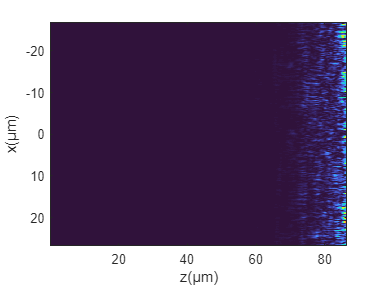

V=-(k0)^2*((RI+n_imm).^2-n_imm^2);
%EvolB=ML1stB(fxx,fyy,2*pi./k0,n_imm,psz,V,U_in,'Vol');
eps=0;
EvolB=MultiLayerBorn(fxx,fyy,lambda,n_imm,ps,V,U_in,eps,'Vol');%.017
%exp(-2*k0*eps*zz(end))
figure; imagesc(zz,x,squeeze(abs(EvolB(end/2,:,:)).^2))
colormap Turbo
xlabel('z(\mum)')
ylabel('x(\mum)')


$$-ie^{i2\pi\sqrt{(n/\lambda)^2-(f_x^2+f_y^2)+i\epsilon}}/{4\pi \sqrt{(n/\lambda)^2-(f_x^2+f_y^2)+i\epsilon}}$$


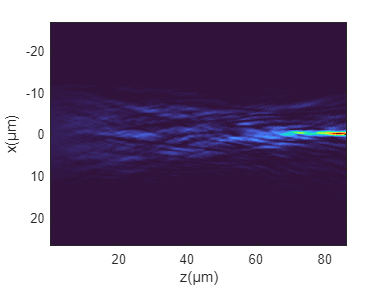

%V=-(k0)^2*((RI+n_imm).^2-n_imm^2);
%EvolB=ML1stB(fxx,fyy,2*pi./k0,n_imm,psz,V,U_in,'Vol');
eps=.00199;
EvolB=MultiLayerBorn(fxx,fyy,lambda,n_imm,ps,V,U_in,eps,'Vol');%.017
%exp(-2*k0*eps*zz(end))
figure; imagesc(zz,x,squeeze(abs(EvolB(end/2,:,:)).^2))
colormap Turbo
xlabel('z(\mum)')
ylabel('x(\mum)')

sum(squeeze(abs(EvolB(:,:,end)).^2),'all')./sum(squeeze(abs(EvolB(:,:,1)).^2),'all')

ans = 1.0628

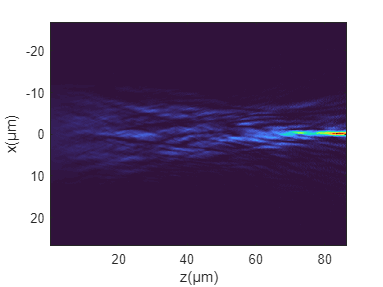

eps=.00178;
EvolB=MultiLayerRytov(fxx,fyy,lambda,n_imm,ps,V,U_in,eps,'Vol');%.017
%exp(-2*k0*eps*zz(end))
figure; imagesc(zz,x,squeeze(abs(EvolB(end/2,:,:)).^2))
colormap Turbo
xlabel('z(\mum)')
ylabel('x(\mum)')

sum(squeeze(abs(EvolB(:,:,end)).^2),'all')./sum(squeeze(abs(EvolB(:,:,1)).^2),'all')

ans = 1.1705

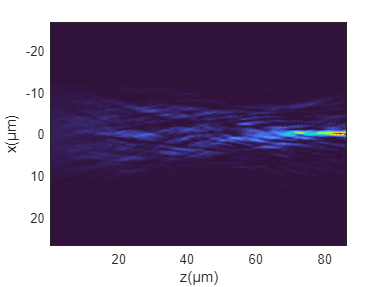

eps=.00178;
EvolB=MultiSlabRytov(fxx,fyy,lambda,n_imm,ps,V,U_in,3,'Vol',eps); % up to third order tayor expansion
%exp(-2*k0*eps*zz(end))
figure; imagesc(zz,x,squeeze(abs(EvolB(end/2,:,:)).^2))
colormap Turbo
xlabel('z(\mum)')
ylabel('x(\mum)')

sum(squeeze(abs(EvolB(:,:,end)).^2),'all')./sum(squeeze(abs(EvolB(:,:,1)).^2),'all')

ans = 1.1689

## Scattering through a phantom

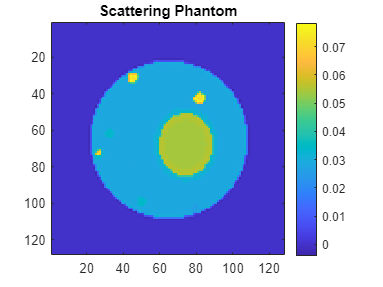

n_media     = 1.33;         % refractive index of media
n_max       = 1.4;          % refractive index of max density feature 
pdar        = 100;           % padding size before running forward model (to avoid edge artifacts)
obj         = makePhantom('phantom.tif',n_media,n_max);     % making phantom
obj=imresize3(obj,[128 128 128]);
obj         = obj-n_media;              % subtracting out global RI difference due to media
figure; imagesc(obj(:,:,50))
axis square
colorbar
title('Scattering Phantom')

obj=padarray(obj,[pdar pdar],0,'both');

%% Reset Grids

pdar        = 100;           % padding size before running forward model (to avoid edge artifacts)
ps          = 0.035*3;                % pixel size (x,y,z) in object space (micron)
lambda      = 0.5;                % central wavelength (micron)
NA          = 1.0;                  % numerical aperture of imaging and detection lens
n_imm       = 1.367;                 % refractive index of immersion media
k0=(2*pi)/lambda;
N           = size(obj,1);%2^7;%2^9;                                  %120+2*pdar; %size(obj,1)+2*pdar;   % lateral pixel dimension of padded object
x           = ps*[-N/2:N/2-1];      % 1D padded axis in x
y=x;
dfx         = 1/(N*ps);             % Fourier spacing of padded axis
[X Y]=meshgrid(x,y);
fx          = dfx*[-N/2:N/2-1];     % 1D padded axis in fx
[fxx,fyy]   = meshgrid(fx,fx);      % 2D padded grid in fx/fy

fx          = ifftshift(fx);        % FFT shifting Fourier axes
fxx         = ifftshift(fxx);       % FFT shifting Fourier axes
fyy         = ifftshift(fyy);       % FFT shifting Fourier axes

k=k0*n_imm;

Scattering potential

V=-(k0)^2*((obj+n_imm).^2-n_imm^2);

eps=.005;           % Absorption term
U_in=ones([N N]); % normally incident plane wave
evolMLBPhantom=ML1stBOG(fxx,fyy,lambda,n_imm,ps,V,U_in,'Vol'); % Original MLB code
sum(squeeze(abs(evolMLBPhantom(:,:,end)).^2),'all')./sum(squeeze(abs(evolMLBPhantom(:,:,1)).^2),'all')

ans = 1.0106

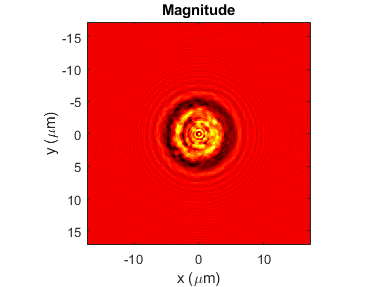

figure;
for ii=1:size(evolMLBPhantom,3)
    
    imagesc(x,x,abs(evolMLBPhantom(:,:,ii)))
    colormap hot
    xlabel('x (\mum)')
    ylabel('y (\mum)')
    axis square
    title('Magnitude')
    
    drawnow;
end